# Varying T1

clear
clc

pa = 7e4; %ambient pressure
Ta = linspace(135,1000,500); %ambient temperature
Mf = 2.8; %free stream mach number
Shock = 1.1; %normal shock strength (before shock mach number)
Mbe = 0.2; %burner entry mach number
Tb = 1700; %maximum burner temperature
bpr = 1; %burner pressure ratio
epr = 1; %exhaust pressure ratio
thrust = 5e5; %required thrust

for i = 1 : length(Ta)
    [A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa,Ta(i),Mf,Shock,Mbe,Tb,bpr,epr,thrust);
end

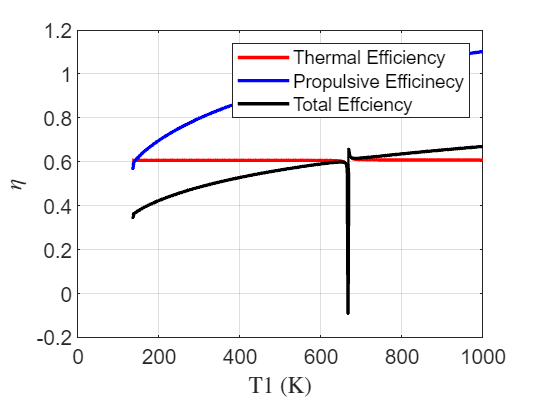

% efficiencies
figure(1)
p1 = plot(Ta,thermeff,'LineWidth',2,'color','r');
hold on
p2 = plot(Ta,propeff,'LineWidth',2,'color','b');
p3 = plot(Ta,propeff.*thermeff,'LineWidth',2,'color','k');
hold off
grid on
xlabel('T1 (K)','Interpreter','latex')
ylabel('$\eta$','Interpreter','latex')
entries = [p1 p2 p3];
legend(entries,'Thermal Efficiency','Propulsive Efficinecy','Total Effciency')
set(gca,'FontSize',12)

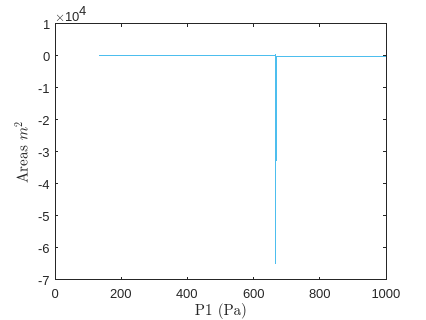


% Areas
figure(2)
plot(Ta,A1)
hold on
plot(Ta,At1)
plot(Ta,Abe)
plot(Ta,Abx)
plot(Ta,At3)
plot(Ta,Ae)
hold off
xlabel('P1 (Pa)','Interpreter','latex')
ylabel('Areas $m^2$','Interpreter','latex')